# CNN Model weight verification and performance testing

Load cifar10testdata and debuggingTest data 

load 'cifar10testdata.mat'
%loading this file defines imrgb and layerResults
load 'debuggingTest.mat'

Display sample image

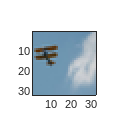

% sample code to show image and access expected results
figure; imagesc(imrgb); truesize(gcf,[64 64]);

% run forward pass on the CNN model with input image 
import model.*
m = model();
output = m.forward(imrgb);

Verfiy whether the results from our implemented model match with those from debuggingTest.mat

% verify expected results
for d = 1:length(layerResults)
    result = layerResults{d};
    model_result = m.layerresults{d};
    sz_comparsion = compare_size(result, model_result); 
    equality_comparsion = compare_double_tensor(result, model_result);
    fprintf('layer %d size check : %d and equality check : %d\n',...
    d, sz_comparsion, equality_comparsion);
end

layer 1 size check : 1 and equality check : 1
layer 2 size check : 1 and equality check : 1
layer 3 size check : 1 and equality check : 1
layer 4 size check : 1 and equality check : 1
layer 5 size check : 1 and equality check : 1
layer 6 size check : 1 and equality check : 1
layer 7 size check : 1 and equality check : 1
layer 8 size check : 1 and equality check : 1
layer 9 size check : 1 and equality check : 1
layer 10 size check : 1 and equality check : 1
layer 11 size check : 1 and equality check : 1
layer 12 size check : 1 and equality check : 1
layer 13 size check : 1 and equality check : 1
layer 14 size check : 1 and equality check : 1
layer 15 size check : 1 and equality check : 1
layer 16 size check : 1 and equality check : 1
layer 17 size check : 1 and equality check : 1
layer 18 size check : 1 and equality check : 1


Figuring out the class based on debugging data

%find most probable class based on debugging data
[maxprob,maxclass] = convertProbToLabel(layerResults{end})

maxprob = 0.5252

maxclass = 1

%note, classlabels is defined in ’cifar10testdata.mat’
fprintf('DEBUGGING RESULT : estimated class is %s with probability %.4f\n',...
classlabels{maxclass},maxprob);

DEBUGGING RESULT : estimated class is airplane with probability 0.5252


Figuring out the class based on model output

%find most probable class based on model output
[maxprob,maxclass] = convertProbToLabel(output)

maxprob = 0.5252

maxclass = 1

%note, classlabels is defined in ’cifar10testdata.mat’
fprintf('MODEL OUTPUT RESULT : estimated class is %s with probability %.4f\n',...
classlabels{maxclass},maxprob);

MODEL OUTPUT RESULT : estimated class is airplane with probability 0.5252


### **Model performance on CIFAR test dataset**

% use for loop to iterate the input testing images
num_of_images = size(imageset, 4)

num_of_images = 10000

predicted_labels = zeros(1, num_of_images);
for index = 1:num_of_images
    if mod(index, 500) == 0
        fprintf('Progress: %d / %d \n', index, num_of_images);
    end
    output = m.forward(imageset(:, :,  :, index));
    [~,predicted_labels(1, index)] = convertProbToLabel(output);
end

Progress: 500 / 10000 
Progress: 1000 / 10000 
Progress: 1500 / 10000 
Progress: 2000 / 10000 
Progress: 2500 / 10000 
Progress: 3000 / 10000 
Progress: 3500 / 10000 
Progress: 4000 / 10000 
Progress: 4500 / 10000 
Progress: 5000 / 10000 
Progress: 5500 / 10000 
Progress: 6000 / 10000 
Progress: 6500 / 10000 
Progress: 7000 / 10000 
Progress: 7500 / 10000 
Progress: 8000 / 10000 
Progress: 8500 / 10000 
Progress: 9000 / 10000 
Progress: 9500 / 10000 
Progress: 10000 / 10000 


Confusion matrix

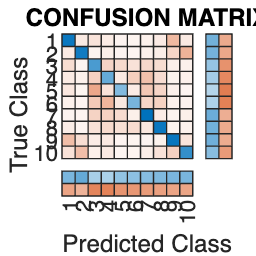

confused =   ConfusionMatrixChart (CONFUSION MATRIX) with properties:

    NormalizedValues: [10×10 double]
         ClassLabels: [10×1 uint8]

  Show all properties


accuracy = 0.4371

[confused, accuracy] = find_confusion(trueclass, uint8(predicted_labels))

Helper functions

function result = compare_double_tensor(d1, d2)
    result = false;
    eps = 1e-6;
    val = sum((abs(d1 - d2) < eps), 'all');
    if val == prod(size(d1), 'all')
        result = true;
    end
end

function result = compare_size(A, B)
    result = false;
    szA = size(A);
    szB = size(B);
    if length(szA) == length(szB)
        count = 0;
        for i=1:length(szB)
           if szA(i) == szB(i)
               count = count + 1;
           end
        end
        if count == length(szB)
            result = true;
        end
    end
end

function [maxprob,maxclass] = convertProbToLabel(inputProb)
    %find most probable class
    classprobvec = squeeze(inputProb);
    [maxprob,maxclass] = max(classprobvec);
end
